# AoI Lab

tic
clear
close all
clc
SetCurrentFile;
dbstop if error

paths = ["./model", "./lib", "./aoi_lab"];
addpath(genpath(paths(2)));
path_util().add_paths(paths);

## 选择

disp(lab_strategy())

  列 1 至 5

    "Manual"    "Random"    "weight-based Random"    "Greedy"    "weight-based Greedy"

  列 6 至 10

    "Proportion"    "ProportionPro"    "ProportionNB"    "ProportionNBPro"    "Ladder"

  列 11 至 14

    "FastLadder"    "LadderPro"    "FastLadderPro"    "weight-based LP"

  列 15 至 19

    "weight-based FLP"    "Hybrid"    "FastHybrid"    "TG"    "proportion-based …"

  列 20

    "MWAoI"



选择前先设置底部的参数

opt = 1;

配置

config = cdtstm_util().mc_switch().config_ex();
config.con_num = 4;
config.fun = {@fun_tsc, @fun_ter, @fun_pn, @fun_lbd};
config.fun_con = {{1,5}, {2,5}, {3,5}, {4,5}};
%保存数据
save_ = true;

运行

============Lab starts============
[2022-08-23 09:25:18] #simulation starts...#
Type: TimeSlot
Random mode:same random
Simulation mode:operate independently
 
[2022-08-23 09:25:18] Simulation Rounds: 1/10
MWAoI:              max arrival interval:12
                    wpAoI_avg:50.505
                    pAoI_max :0.99
----------------------------------------------
LadderPro:          max arrival interval:12
                    wpAoI_avg:50.5
                    pAoI_max :0.99
----------------------------------------------
 
[2022-08-23 09:25:19] Simulation Rounds: 2/10
MWAoI:              max arrival interval:14
                    wpAoI_avg:67.3767
                    pAoI_max :1
----------------------------------------------
LadderPro:          max arrival interval:14
                    wpAoI_avg:67.3433
                    pAoI_max :1.03
----------------------------------------------
 
[2022-08-23 09:25:20] Simulation Rounds: 3/10
MWAoI:              max arrival interval:16
      

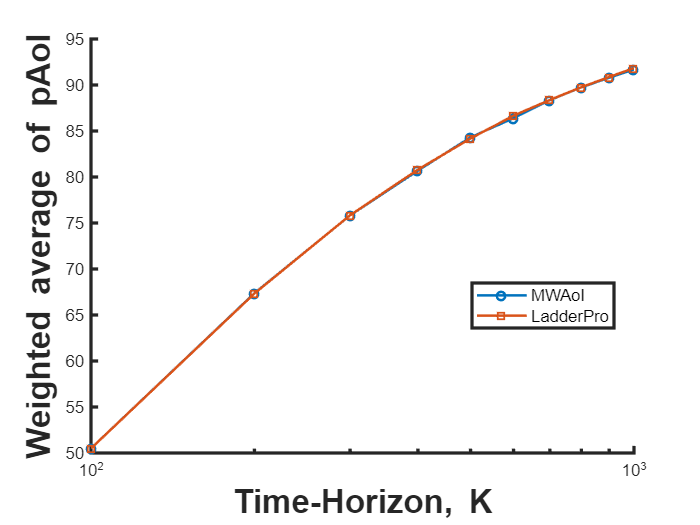

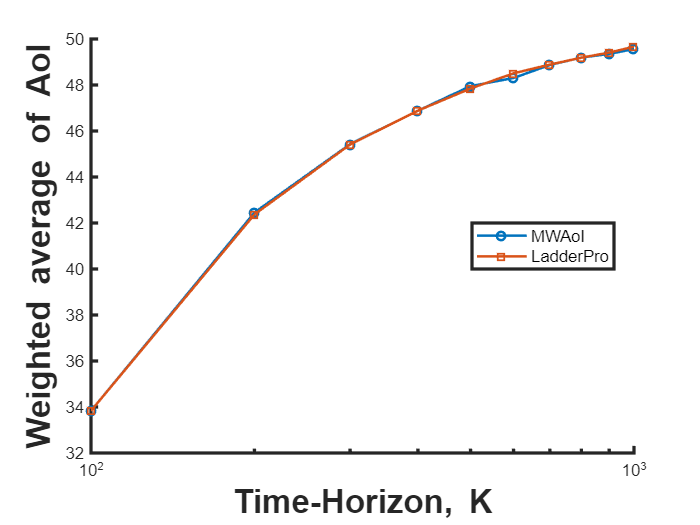

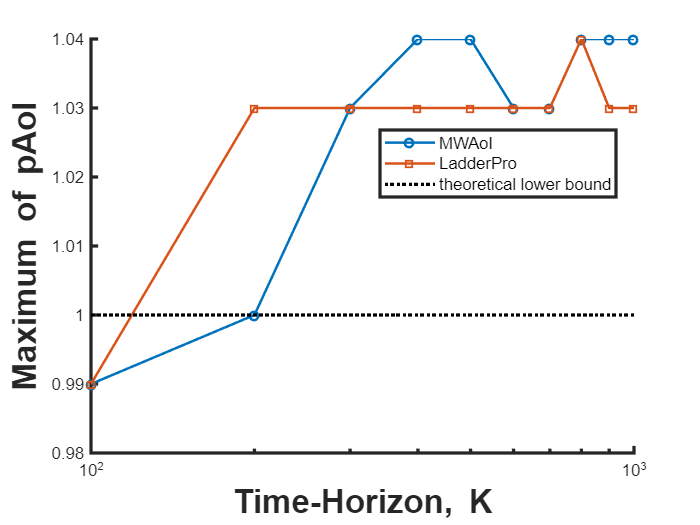

数据已存储在：./data/23-Aug-2022/[09_25_35]TSC_ 1e+3_100_0.5--0.5_0--0


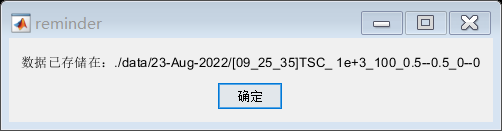

run_lab(opt, config, save_);

path_util().rm_paths(paths);
toc

历时 23.718975 秒。


## 参数配置

### 变时隙

function stc = fun_tsc
    stc = lab_init_stc(false);
    stc.strategy = ["MWAoI", "LadderPro"];
    stc.terminal_num = 100;
    stc.ts = ((1:10)*1e+2)';%([1, 5, 1e+1, 5e+1, 1e+2 5e+2] * 1e+4)'
    stc.pn = (linspace(0, 0, stc.terminal_num))';
    stc.lambda = (linspace(0.5, 0.5, stc.terminal_num))'; 
    stc.alpha = (linspace(1,  1, stc.terminal_num))';
end

### 变终端数

function stc = fun_ter
    stc = lab_init_stc(false);
    stc.type = "TER";
    stc.strategy = ["MWAoI", "LadderPro"];
    stc.terminal_num = ([5 10 40 60 80 100])';
    stc.ts = 1e+3;
    
    stc.lambda = cell(length(stc.terminal_num), 1);
    stc.pn = cell(size(stc.lambda));
    stc.alpha = cell(size(stc.lambda));
    for i = 1:length(stc.terminal_num)
        stc.lambda{i} = (linspace(0.5, 0.5, stc.terminal_num(i)))';
        stc.pn{i} = 0*ones(stc.terminal_num(i), 1);
        stc.alpha{i} = (linspace(1, 1, stc.terminal_num(i)))';
    end
end

### 变传输失败概率

function stc = fun_pn
    stc = lab_init_stc(false);
    stc.type = "PnC";
    stc.strategy = ["MWAoI", "LadderPro"];
    stc.terminal_num = 100;
    stc.ts = 1e+3;
    stc.pn = (0.05:0.05:0.95)'; 
    stc.alpha = (linspace(1,1, stc.terminal_num))';
    stc.lambda = (linspace(0.1, 0.1, stc.terminal_num))';
end

### 变到达率

function stc = fun_lbd
    stc = lab_init_stc(false);
    stc.type = "LBN";
    stc.strategy = ["MWAoI", "LadderPro"];
    stc.terminal_num = 100;
    stc.ts = 1e+3;
    stc.pn = (linspace(0.1, 0.1, stc.terminal_num))';
    stc.alpha = (linspace(1, 1, stc.terminal_num))';
    stc.lambda = (0.05:0.05:0.95)'; 
end